Let's start by creating some data on which to perform inference.

rng(14);
n=1500;
rand1 = exprnd(.16,[1,floor(n/3)]);
rand1 = rand1(rand1<=0.6);
rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);

y = ([rand1])

y =     0.1065    0.0412    0.0222    0.1875    0.0069    0.1068    0.1832    0.0988    0.2414    0.0344    0.1716    0.0989    0.0633    0.2497    0.0112    0.1573    0.0455    0.0433    0.0222    0.3530    0.1926    0.1191    0.0634    0.2170    0.0568    0.0672    0.2726    0.1813    0.0191    0.3976    0.0468    0.4440    0.0500    0.0476    0.1435    0.0014    0.1270    0.2658    0.1672    0.0537    0.1646    0.4742    0.1844    0.0002    0.1992    0.1236    0.0492    0.0093    0.2785    0.2479


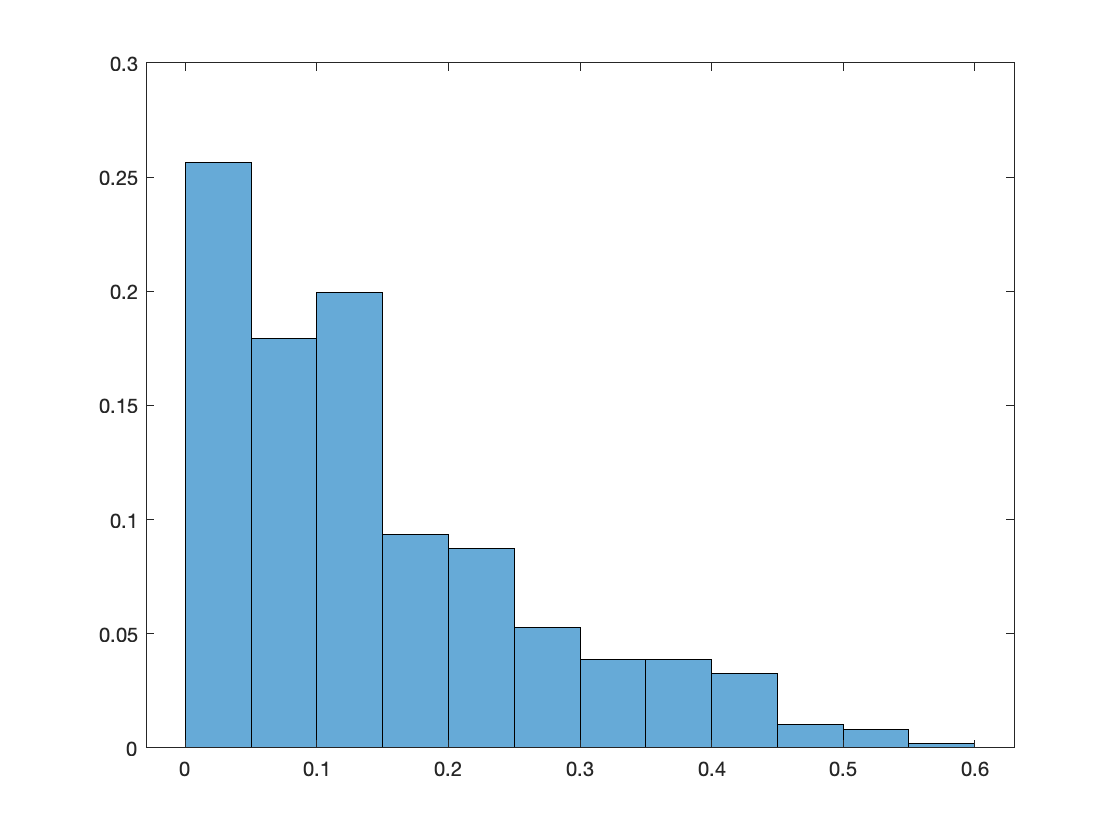

histogram(y, 'Normalization','probability')


% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0


% knots = [-0.5, 0.0, 0.1, 0.21, 0.31, 0.41, 0.51, 0.6, 0.71, 0.81, 0.91, 1, 1.5];
% d = 11;
knots = [-1e100, 0, 0.11, 0.21, 0.5, 0.6, 0.7, 0.9, 1, 1e100];
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
initial = [-2, log(0.25), log(0.2), log(0.1), log(0.05), -3, -4, -5];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -1.1356    0.7070    1.3663   -0.2690   -2.4594   -2.4172   -3.6868   -4.9541


We'll select knots based on the graphic, although more principled methods exist.

% Arbitrarily choosing the starting value, with dimension parameter_dim:
data = y;
q0 = initial_guess';
nllFunc = @(x) negLog_fiducial_likelihood(knots,x,data);
conFunc = constraintFunc;

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 10000;
runTime = 15; % Time per run in seconds
nTrials = 1000;
doPrint = false;

samplers = struct([]);

h = 1e-6;
M = 1;
L = 1;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 1)...

Performing a total of 10000 iterations.
Finished 1000 iterations.
Finished 2000 iterations.
Finished 3000 iterations.
Finished 4000 iterations.
Finished 5000 iterations.
Finished 6000 iterations.
Finished 7000 iterations.
Finished 8000 iterations.
Finished 9000 iterations.
Finished 10000 iterations.


50 samples: 

mean(samplerStats{1,1}.accepted)

ans = 0.0458

Qs = samplerQs{1,1};
save("HMC_logsplineDraws.mat",'Qs');

Qs = load("HMC_logsplineDraws.mat").Qs

Qs =    -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356   -1.1356
    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    0.7070    


samples = Qs;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

chosen_theta = samples(:,min_index)

chosen_theta =    -1.1356
    0.7070
    1.3663
   -0.2690
   -2.4594
   -2.4172
   -3.6868
   -4.9541


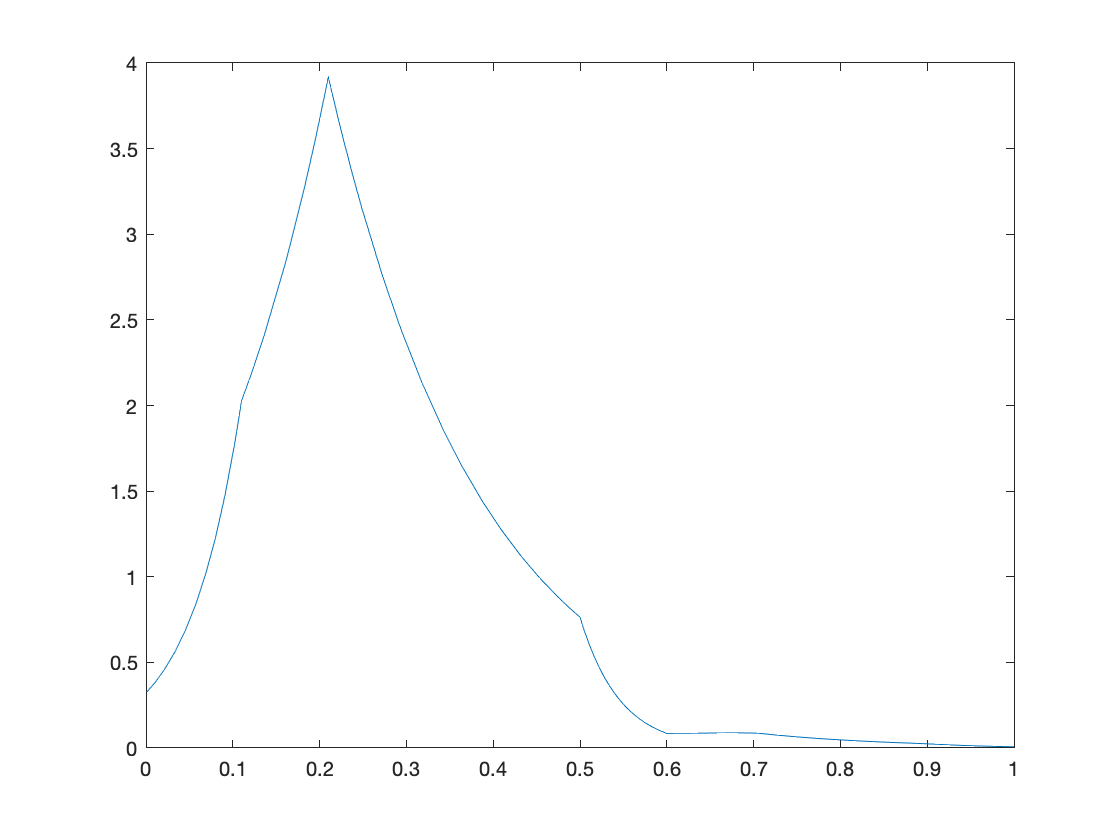


syms func(x)
% func(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%                     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%                     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%                     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%                     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(7))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%                     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(8))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%                     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(9))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%                     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(10))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
%                     (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(11))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
%                     (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(12))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))) );

func(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))));


% fplot(y, [0,1])
[f,yi] = ksdensity(y);
fplot(func, [0,1])

% hold on
% plot(yi,f)
% hold off

double(int(func, 0, 1))

ans = 1.0000

% double(int(f, 0, 1))